# Bernstein approximation

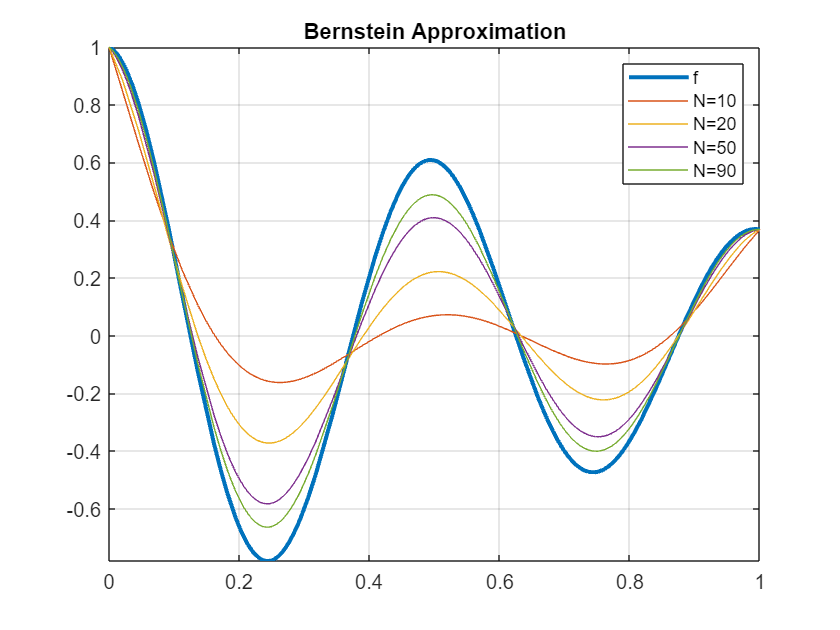

syms x real
f = cos(4*pi*x).* exp(-x); % f is continuous on [0 1] ( another symbolic object )

figure
fplot(f, [0,1], LineWidth=2)
hold on
grid on
title("Bernstein Approximation")
i =1;
for N = [10,20,50,90]
    Bf = bernstein (f, N, x); % using de Casteljau 's algorithm
    fplot(Bf, [0,1])
    i = i+1;
end
legend(["f" "N="+ [10,20,50,90]])